# Cavity flow with Physics-Informed Neural Networks

Solve cavity flow governed by 2d steady Navier-Stokes equations and continuity equation, using a Physics-Informed Neural Network (PINN).

The 2d, steady Navier-Stokes equations for an incompressible fluid are:


$$\frac{\partial u}{\partial x} + \frac{\partial v}{\partial y} = 0 
$$



$$u\frac{\partial u}{\partial x} + v\frac{\partial u}{\partial y} + \frac{\partial p}{\partial x} - \frac{1}{Re}\bigg( \frac{\partial^2 u}{\partial x^2} + \frac{\partial^2 u}{\partial y^2} \bigg) = 0$$



$$u\frac{\partial v}{\partial x} + v\frac{\partial v}{\partial y} + \frac{\partial p}{\partial y} - \frac{1}{Re}\bigg( \frac{\partial^2 v}{\partial x^2} + \frac{\partial^2 v}{\partial y^2} \bigg) = 0$$


$(x,y)$ are the spatial coordinates, $(u,v)$ is the fluid velocity, $p$ is the pressure and $Re$ is the Reynolds number.

In order to automatically satisfy the continuity equation we use the stream function $\psi$, such that $u = \partial\psi / \partial y$ and $v = -\partial\psi /\partial x$. The cavity is defined as the square domain $[0,1]\times [0,1]$. The boundary conditions are $(u,v)=(1,0)$ at the top boundary and $(u,v)=(0,0)$ at the other boundaries. Additionally, $\psi=0$ is assumed on all the boundaries. The Reynolds number is $Re=100$. 

The PINNs model takes the spatial coordinates $(x,y$) as inputs and returns the streamfunction and pressure $(\psi, p)$ as outputs.

This work is inspired by the following GitHub repo: [https://github.com/okada39/pinn_cavity](https://github.com/okada39/pinn_cavity) 

## Set parameters.

Re = 100;
u0 = 1;

## Create network

The core network architecture is a standard multi-layer perceptron (MLP) with `numHiddenUnits=32` and swish activations. We use separate inputs for `x` and `y` because it makes it easier to compute derivatives with respect to these inputs later when imposing the PINNs loss. In addition to the MLP, we use anchor functions to impose the $\psi=0$ boundary condition. For example, the anchor function in $x$ ensures that the boundary condition is strictly enforced by multiplying the unconstrained network estimate for $\psi$ by the function $4x(1-x)$ -- which is $0$ at the boundaries (i.e. when $x=0$ or $x=1$). The factor $4$ is chosen so that the anchor function has a maximum of one. We include two anchor functions, one for the $x$-coordinate and one for the $y$-coordinate, then multiply them with the "free" $\psi$ estimation to produce the final output for $\psi$.

% Create basic MLP network architecture with two inputs (x,y) and two
% outputs (psi,p).
numHiddenUnits = 32;
net = dlnetwork();
layers = [ featureInputLayer(1, Name="x")
    concatenationLayer(1, 2)
    fullyConnectedLayer(numHiddenUnits)
    swishLayer()
    fullyConnectedLayer(numHiddenUnits)
    swishLayer()
    fullyConnectedLayer(numHiddenUnits)
    swishLayer() 
    fullyConnectedLayer(numHiddenUnits)
    swishLayer(Name="swishout")
    fullyConnectedLayer(1, Name="psiFree") ];
net = addLayers(net, layers);
net = addLayers(net, fullyConnectedLayer(1, Name="p"));
net = connectLayers(net, "swishout", "p");
net = addInputLayer(net, featureInputLayer(1, Name="y"), Initialize=false);

% Add anchor functions to strictly enforce boundary conditions on the
% streamfunction.
net = addLayers(net, [functionLayer(@(x)4.*x.*(1-x), Name="anchorX", Acceleratable=true); multiplicationLayer(3, Name="psi")]);
net = addLayers(net, functionLayer(@(y)4.*y.*(1-y), Name="anchorY", Acceleratable=true));
net = connectLayers(net, "x", "anchorX");
net = connectLayers(net, "y", "anchorY");
net = connectLayers(net, "anchorY", "psi/in2");
net = connectLayers(net, "psiFree", "psi/in3");

% Make sure outputs are ordered (psi,p).
net.OutputNames = ["psi", "p"];

% Initialize the network and cast to double precision.
net = initialize(net);
net = dlupdate(@double, net);

% Visually inspect the network.
analyzeNetwork(net)

## Create training input

numTrainSamples = 1e4;
xyEquation = rand([numTrainSamples 2]);

numBoundarySamples = floor(numTrainSamples/2);
xyTopBottom = rand([numBoundarySamples 2]); % top-bottom boundaries.
xyTopBottom(:, 2) = round(xyTopBottom(:, 2)); % y-position is 0 or 1.

xyLeftRight = rand([numBoundarySamples 2]); % left-right boundaries.
xyLeftRight(:, 1) = round(xyLeftRight(:, 1)); % x-position is 0 or 1.

xyBoundary = cat(1, xyTopBottom, xyLeftRight);
idxPerm = randperm(size(xyBoundary, 1));
xyBoundary = xyBoundary(idxPerm, :);

## Create training output

zeroVector = zeros([numTrainSamples 1]);
uvBoundary = [zeroVector zeroVector];
uvBoundary(:, 1) = u0.*floor( xyBoundary(:, 2) );

## Train the model

Train using the L-BFGS optimizer, using a GPU is one is available.

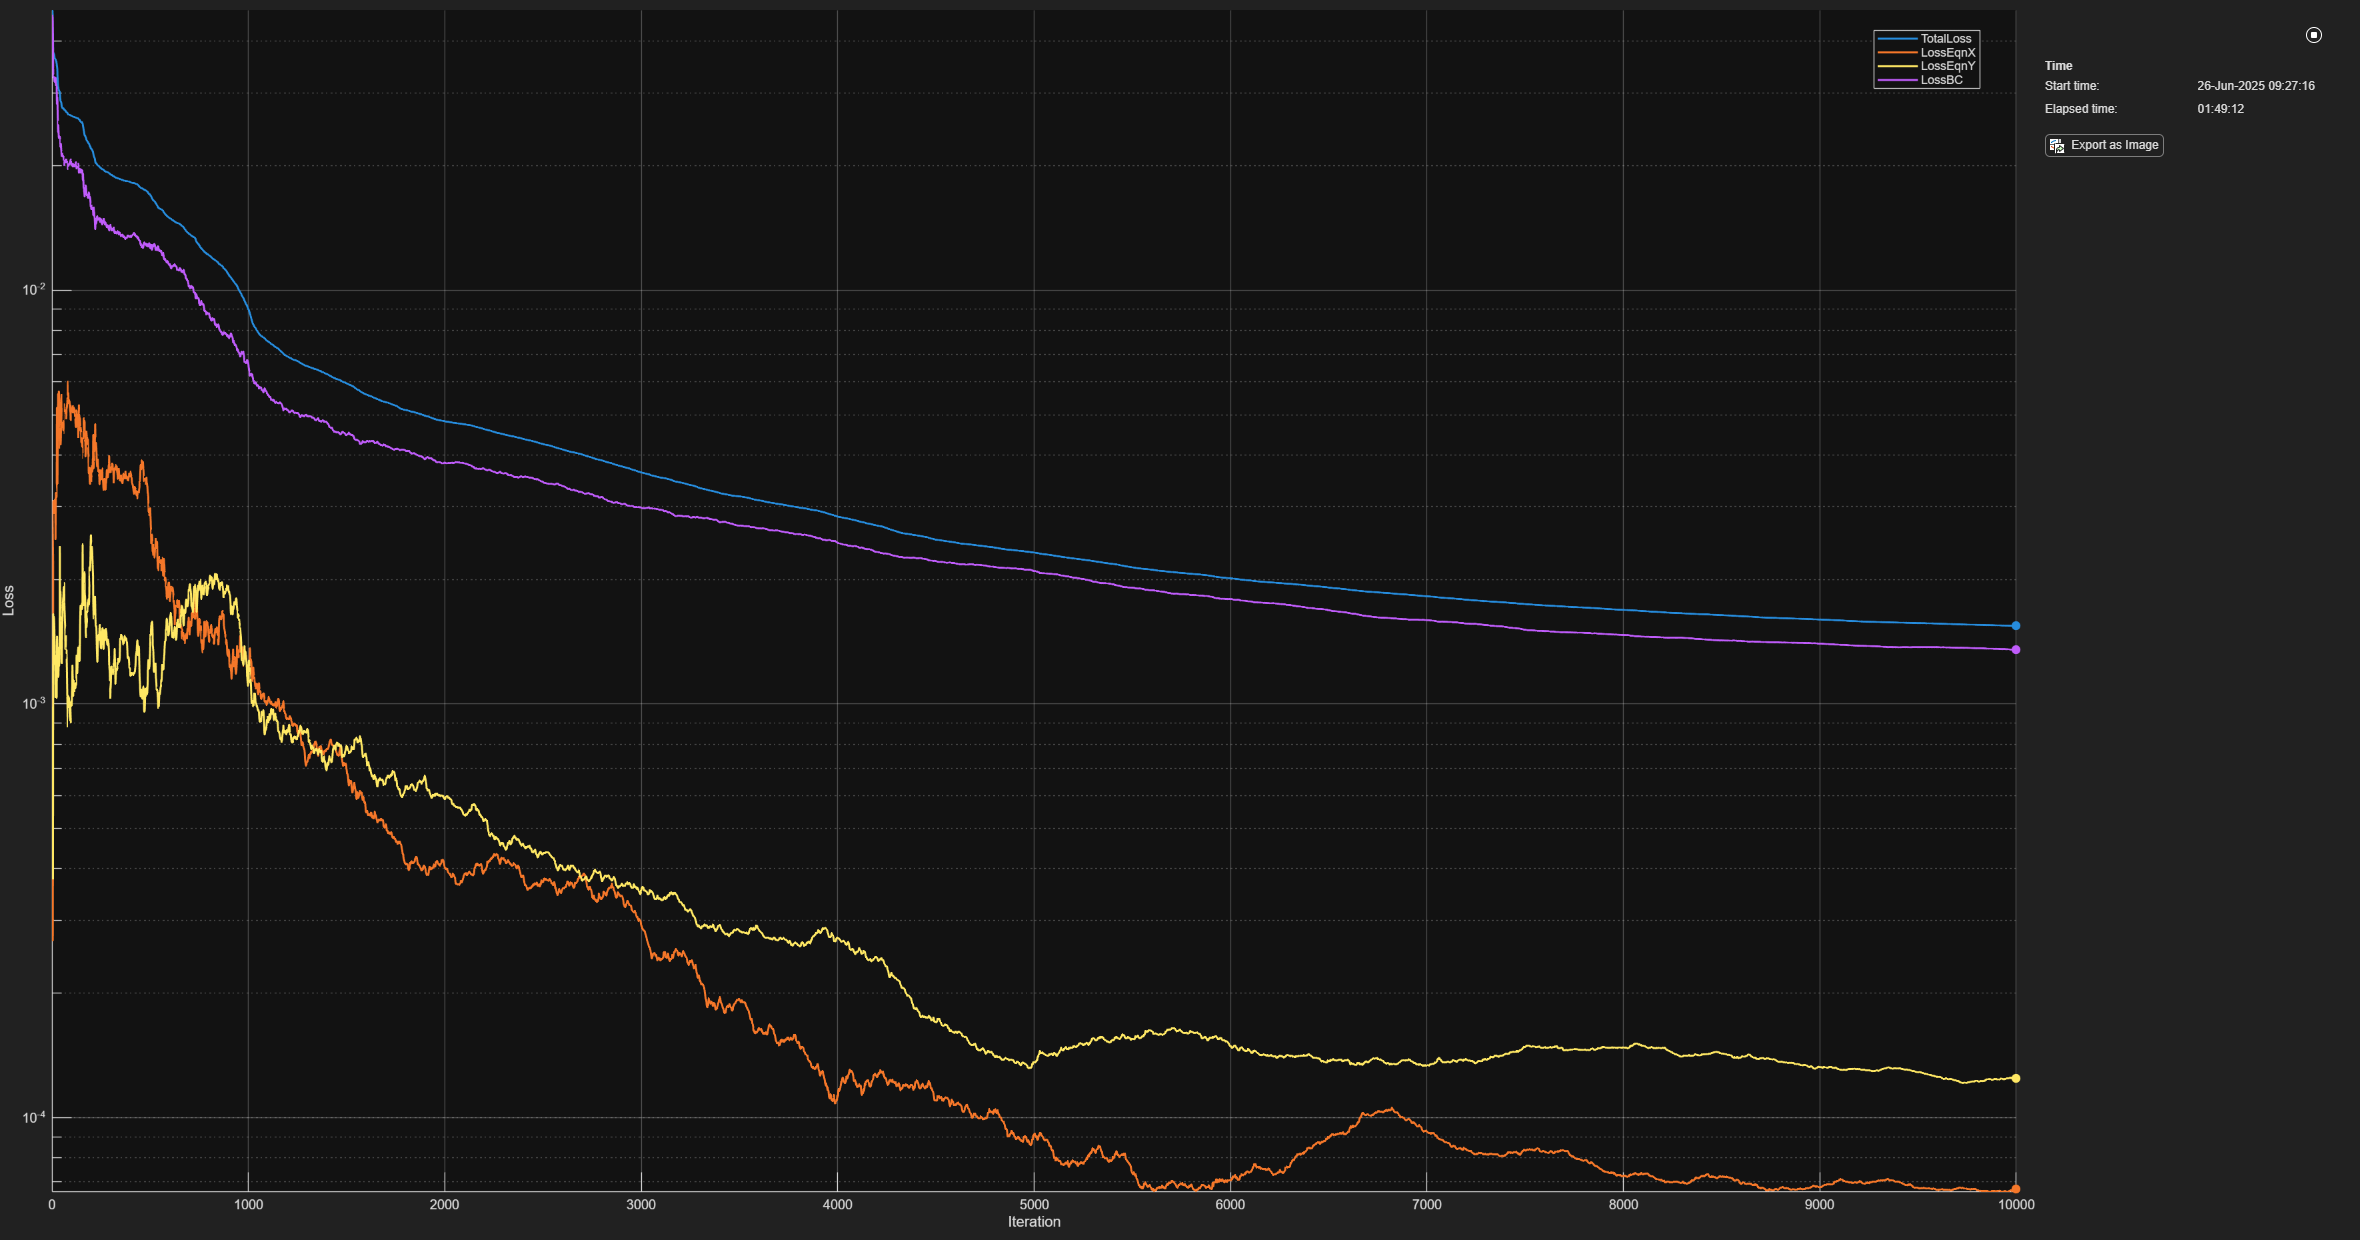

% Prepare training data.
xyEquation = dlarray(xyEquation);
xyBoundary = dlarray(xyBoundary);
if canUseGPU
    xyEquation = gpuArray(xyEquation);
    xyBoundary = gpuArray(xyBoundary);
end

% Create training progress plot.
monitor = trainingProgressMonitor();
monitor.XLabel = "Iteration"; 
monitor.Metrics = ["TotalLoss", "LossEqnX", "LossEqnY", "LossBC"];
groupSubPlot(monitor, "Loss", ["TotalLoss", "LossEqnX", "LossEqnY", "LossBC"])
yscale(monitor, "Loss", "log");

% Train with L-BFGS.
maxIterations = 1e4;
solverState = [];
lossFcn = dlaccelerate(@pinnsLossFunction);
lbfgsLossFcn = @(n)dlfeval(lossFcn, n, xyEquation, xyBoundary, zeroVector, uvBoundary, Re);
for iteration = 1:maxIterations
    [net, solverState] = lbfgsupdate(net, lbfgsLossFcn, solverState, NumLossFunctionOutputs=5);

    % loss = extractdata(solverState.Loss);
    additionalLosses = solverState.AdditionalLossFunctionOutputs;
    % additionalLosses = cellfun(@extractdata, additionalLosses);
    recordMetrics(monitor, ...
        iteration, ...
        TotalLoss=solverState.Loss, ...
        LossEqnX=additionalLosses{1}, ...
        LossEqnY=additionalLosses{2}, ...
        LossBC=additionalLosses{3});
end

## Plot predictions

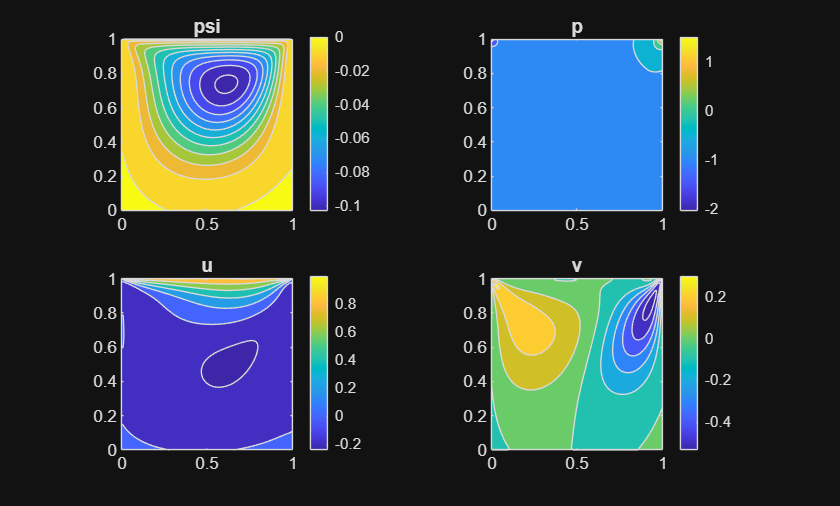

% Create test set using meshgrid.
numTestSamples = 100;
x = linspace(0, 1, numTestSamples)';
y = x;
[xt, yt] = meshgrid(x, y);

% Flatten gridpoints and prepare data.
xTest = dlarray(xt(:));
yTest = dlarray(yt(:));
if canUseGPU
    xTest = gpuArray(xTest);
    yTest = gpuArray(yTest);
end

% Evaluate the network.
[psiTest, pTest, uTest, vTest] = dlfeval(@calculateStreamfunctionPressureAndVelocity, net, xTest, yTest);

% Return predictions to grid and plot.
ut = unflattenAndExtract(uTest, numTestSamples);
vt = unflattenAndExtract(vTest, numTestSamples);
pt = unflattenAndExtract(pTest, numTestSamples);
psit = unflattenAndExtract(psiTest, numTestSamples);

figure; 
subplot(2,2,1)
contourf(xt, yt, psit)
colorbar
axis equal
title('psi')

subplot(2,2,2)
contourf(xt, yt, pt)
colorbar
axis equal
title('p')

subplot(2,2,3)
contourf(xt, yt, ut)
colorbar
axis equal
title('u')

subplot(2,2,4)
contourf(xt, yt, vt)
colorbar
axis equal
title('v')

## Loss function and helper functions

function [loss, grads, lossEqnX, lossEqnY, lossBC] = pinnsLossFunction(net, xyEquation, xyBoundary, zeroVector, uvBoundary, Re)

% Get model outputs at interior points.
xeq = xyEquation(:, 1);
yeq = xyEquation(:, 2);
[psi, p] = forward(net, xeq, yeq);

% Compute gradients.
u = dljacobian(psi', yeq, 1);
v = -1.*dljacobian(psi', xeq, 1);

ux = dljacobian(u', xeq, 1);
uy = dljacobian(u', yeq, 1);
uxx = dljacobian(ux', xeq, 1);
uyy = dljacobian(uy', yeq, 1);

vx = dljacobian(v', xeq, 1);
vy = dljacobian(v', yeq, 1);
vxx = dljacobian(vx', xeq, 1);
vyy = dljacobian(vy', yeq, 1);

px = dljacobian(p', xeq, 1);
py = dljacobian(p', yeq, 1);

% Momentum equations.
lx = u.*ux + v.*uy + px - (1/Re).*(uxx + uyy);
ly = u.*vx + v.*vy + py - (1/Re).*(vxx + vyy);

% Combine for equation loss.
lossEqnX = logCoshLoss(lx, zeroVector);
lossEqnY = logCoshLoss(ly, zeroVector);

% Get model outputs at boundary points.
xbd = xyBoundary(:, 1);
ybd = xyBoundary(:, 2);
psibd = forward(net, xbd, ybd);

ubd = dljacobian(psibd', ybd, 1);
vbd = -1.*dljacobian(psibd', xbd, 1);

uvbd = cat(2, ubd, vbd);
lossBC = logCoshLoss(uvbd, uvBoundary);

% Total loss and model gradients
loss = lossEqnX + lossEqnY + lossBC;
grads = dlgradient(loss, net.Learnables);
end

function loss = logCoshLoss(y, t)
% log-cosh loss function
e = y - t;
loss = mean( log(cosh(e)), 'all' );
end

function [psi, p, u, v] = calculateStreamfunctionPressureAndVelocity(net, x, y)
% Compute the streamfunction psi, pressure p and velocity (u,v) given
% input positions (x,y).
[psi, p] = forward(net, x, y);
u = dljacobian(psi', y, 1);
v = -1.*dljacobian(psi', x, 1);
end

function x = unflattenAndExtract(xflat, sz)
x = reshape(xflat, [sz sz]);
x = extractdata(x);
end